clear;
clc;

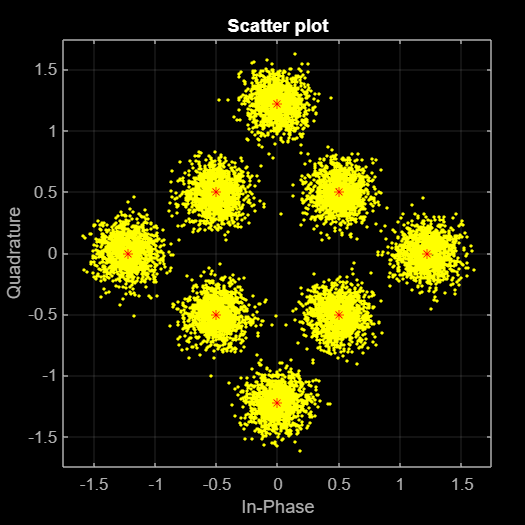

%% Building the constellation for QPSK
c = [0.5+0.5*1i, 0.5-0.5*1i, -0.5+0.5*1i, -0.5-0.5*1i...
    sqrt(3/2), -sqrt(3/2), sqrt(3/2)*1i, -sqrt(3/2)*1i];
sigpower = pow2db(mean(abs(c).^2));
M = length(c);

x = randi([0 M-1],10^4,1);
mod_x = genqammod(x,c);

y = awgn(mod_x,15,sigpower);

h = scatterplot(y);
hold on
scatterplot(c,[],[],'r*',h)
grid
hold off

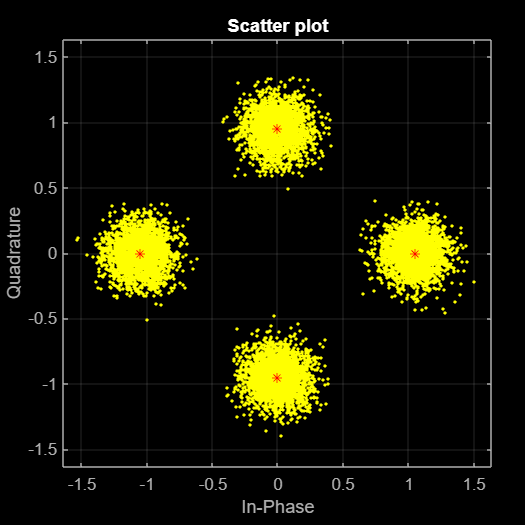

c_4design = [-sqrt(1.1), sqrt(0.9)*1i, -sqrt(0.9)*1i, sqrt(1.1)];
sigpower = pow2db(mean(abs(c_4design).^2));
M = length(c_4design);

x = randi([0 M-1],10^4,1);
mod_x = genqammod(x,c_4design);

y = awgn(mod_x,15,sigpower);

h = scatterplot(y);
hold on
scatterplot(c_4design,[],[],'r*',h)
grid